## Définition des variables

Dans cette section nous allons définir les variables qui vons nous être utiles pour la modélisaton.

### Variables pour les degrées de libertés (DDL)

Le tableau suivant utilise la notation définie par SNAME(1950).

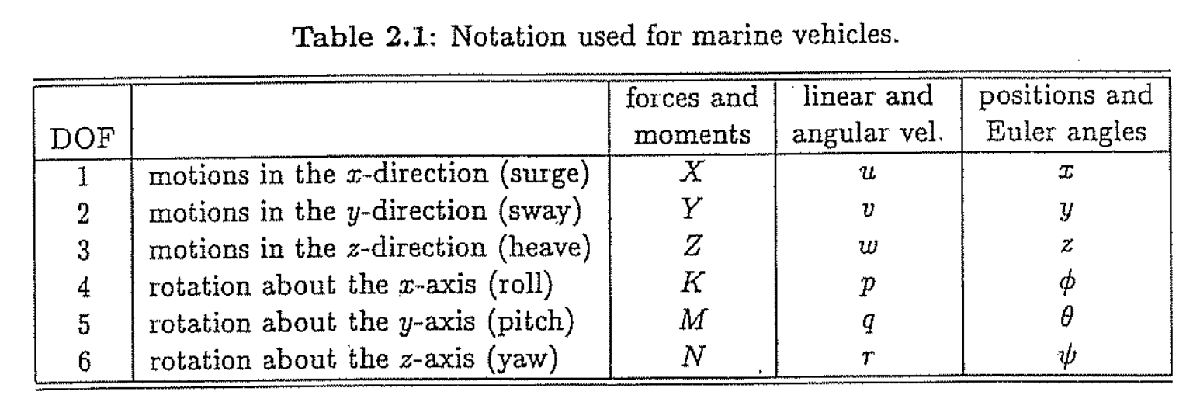

Étant donné que nous voulons utiliser les quaternions, nous n'allons pas définir les angles d'Euler

clear;
sympref('MatrixWithSquareBrackets',true)

ans = logical
   1


   
% Définir les forces et moments
    syms X Y Z K M N
    syms Fm
    syms tauE
    
% Définir les vitesses linéaires et angulaires
    syms u v w p q r

% Définir les positions linéaires
    syms x y z
    
% Définir les angle d'euler
    syms phi theta psi
    
% Définir les entrées système (Thruster)
    syms ('U',[8,1])

% Définir les forces externes et perturbations
    syms ('F_ext',[6,1])
    
% Condition Initials
    syms ('Ne_0',[7,1])
    syms ('N_0',[6,1])
    syms ('V_0',[6,1])
    
% Variable de perturbation
    syms ('Delta_Ne',[7,1])
    syms ('Delta_V',[6,1])
    
    disp(Delta_Ne)

$$\left[\begin{array}{c} \Delta_{\mathrm{Ne1}}\\ \Delta_{\mathrm{Ne2}}\\ \Delta_{\mathrm{Ne3}}\\ \Delta_{\mathrm{Ne4}}\\ \Delta_{\mathrm{Ne5}}\\ \Delta_{\mathrm{Ne6}}\\ \Delta_{\mathrm{Ne7}} \end{array}\right]$$

### Variables pour le quaternion

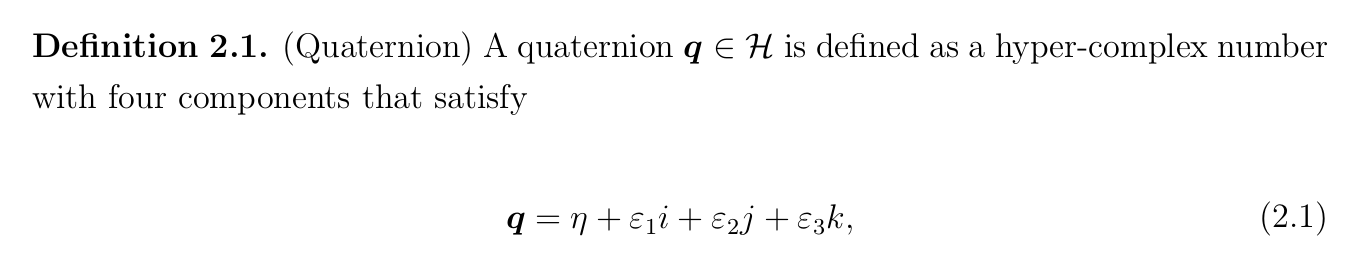

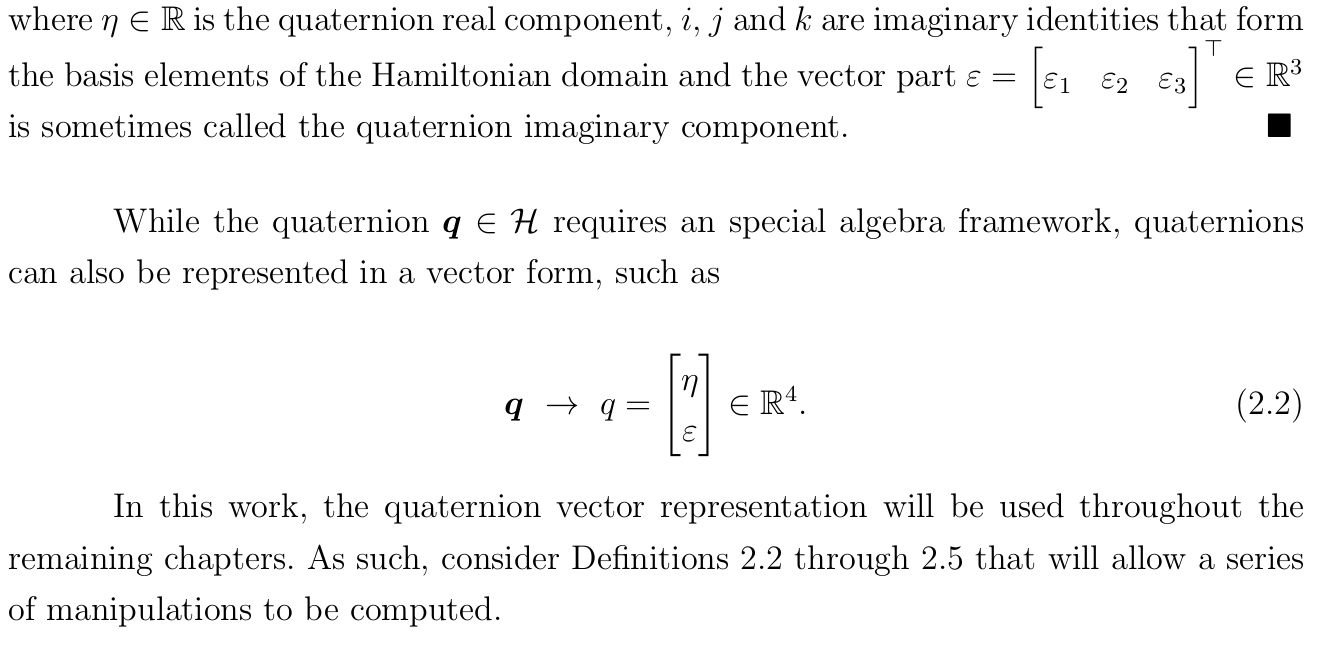

    % Définir la partie scalaire
        syms eta;
        
    % Définir la partie vectorielle
        syms('epsilon',[3,1]);
    
    % Définir le quaternion  
        e=[eta; epsilon];
        
  

### Constante du modèle physique

% distance truster x y z selon centre geommétrique (Constantes)
% D14 distance thruster 1 a 4. (Constantes)
% D58 distance thruster 5 a 8. (Constantes)
% a14 angle thruster 1 a 4. (Constantes)
% dz distance entre les increments sur le frame. (Constantes)
% PZ position des truster sur le frame. (Constantes)
    syms('D14',[1 3]); syms('D58',[1 3]) ; syms a14 dz ; syms ('PZ',[1,4]);

% masse, volume du prototype et hauteur sub (Constantes)
    syms mass volume height

% coefficient de drag (Constantes)
    syms ('CD_L',[1, 6])    % Lineaire
    syms ('CD_Q', [1, 6]);  % Quadratique

% aire de surface du sub (Constantes)
    syms ('AF', [1, 3]);

% matrice d'inertie (Constantes)
    syms ('I', [3, 3]);

% centre de gravité RG et centre de flotataison RB (Constantes)
    syms ('RG',[3 1]); syms('RB',[3 1])
    
% Constantes physique (densité de leau et accélération gravitationel)
    syms rho g


### Regroupement des variables

Nous allons par la suite regrouper les variables

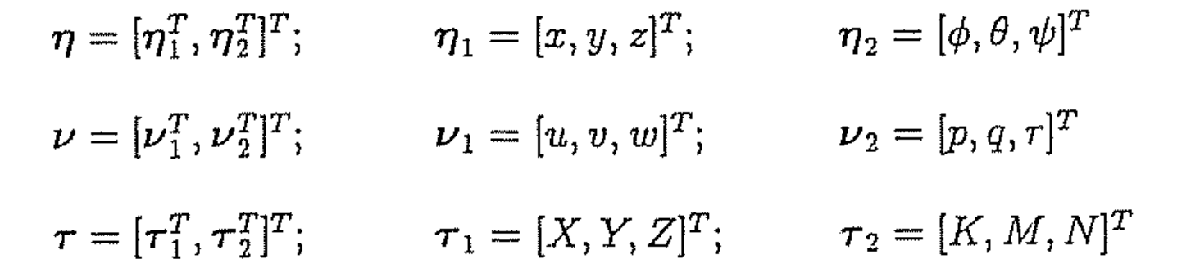

% Position et Orientation 
    n1 = [x,y,z].';
    n2 = [phi, theta, psi].';
    
    Ne = [n1;n2]

$$Ne = \left[\begin{array}{c} x\\ y\\ z\\ \varphi \\ \theta \\ \psi \end{array}\right]$$

    Nq =[n1;e]

$$Nq = \left[\begin{array}{c} x\\ y\\ z\\ \eta \\ \epsilon_{1}\\ \epsilon_{2}\\ \epsilon_{3} \end{array}\right]$$

    
% Vitesses
    v1=[u,v,w].';
    v2=[p,q,r].';
    V=[v1;v2]

$$V = \left[\begin{array}{c} u\\ v\\ w\\ p\\ q\\ r \end{array}\right]$$

    
% Forces et moments
   Fm=[X,Y,Z,K,M,N].';
   

% Constance Mecanique
   constMec = [D14 D58 a14 dz PZ mass volume height AF...
             I(1,:) I(2,:) I(3,:) RG.' RB.' CD_L CD_Q rho g];

% Perturbation + initial
  NODN =N_0+V_0

$$NODN = \left[\begin{array}{c} N_{01}+V_{01}\\ N_{02}+V_{02}\\ N_{03}+V_{03}\\ N_{04}+V_{04}\\ N_{05}+V_{05}\\ N_{06}+V_{06} \end{array}\right]$$

## Équation cinématique du mouvement (quaternion)

### Transformation de la vitesse linéaire

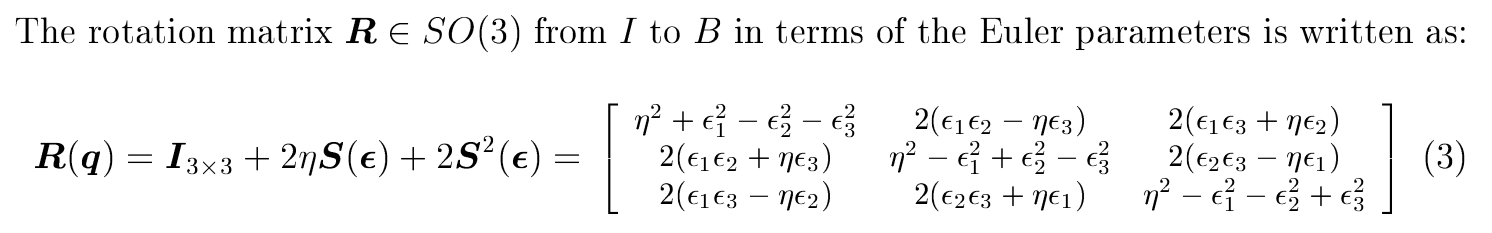

    % Équation 3
    E1=eye(3)+2*eta*skew(epsilon)+2*skew(epsilon)^2

$$E1 = \left[\begin{array}{ccc} -2\,{\epsilon_{2}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{2}}^{2}+1 \end{array}\right]$$

    
%     % Équation 2.24 (Fossen)
%     EE1=[(eta^2-epsilon.'*epsilon)*eye(3)+2*epsilon*epsilon.'-2*eta*skew(epsilon)].'
  

### Transformation de la vitesse angulaire

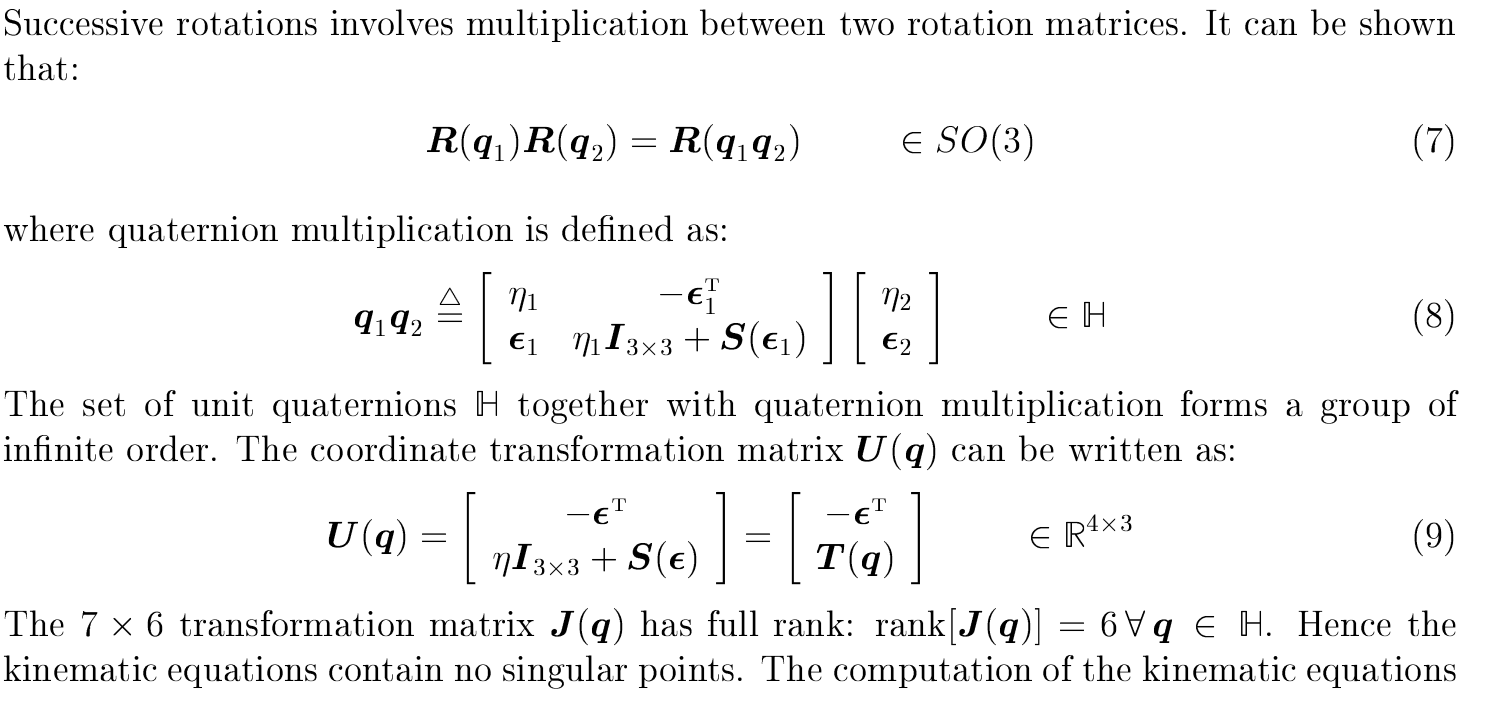

   E2=[-epsilon.';eta*eye(3)+skew(epsilon)]

$$E2 = \left[\begin{array}{ccc} -\epsilon_{1} & -\epsilon_{2} & -\epsilon_{3}\\ \eta & -\epsilon_{3} & \epsilon_{2}\\ \epsilon_{3} & \eta & -\epsilon_{1}\\ -\epsilon_{2} & \epsilon_{1} & \eta \end{array}\right]$$

### Matrice de transformation

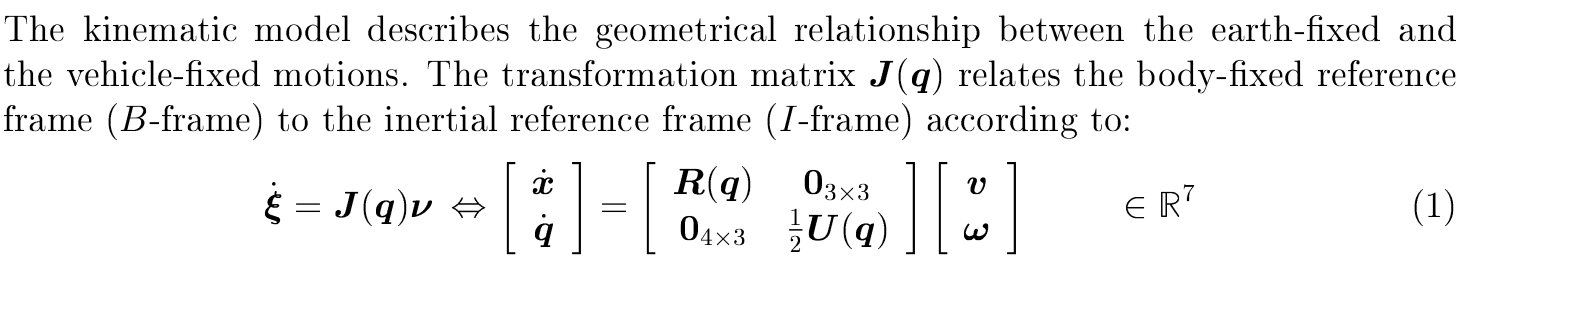

% Définir la matrice de transformation J(q)
   Jq=[E1,zeros(3,3);
   zeros(4,3),(1/2)*E2]

$$Jq = \left[\begin{array}{cccccc} -2\,{\epsilon_{2}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta & 0 & 0 & 0\\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta & 0 & 0 & 0\\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{2}}^{2}+1 & 0 & 0 & 0\\ 0 & 0 & 0 & -\frac{\epsilon_{1}}{2} & -\frac{\epsilon_{2}}{2} & -\frac{\epsilon_{3}}{2}\\ 0 & 0 & 0 & \frac{\eta }{2} & -\frac{\epsilon_{3}}{2} & \frac{\epsilon_{2}}{2}\\ 0 & 0 & 0 & \frac{\epsilon_{3}}{2} & \frac{\eta }{2} & -\frac{\epsilon_{1}}{2}\\ 0 & 0 & 0 & -\frac{\epsilon_{2}}{2} & \frac{\epsilon_{1}}{2} & \frac{\eta }{2} \end{array}\right]$$

## Équation cinématique du mouvement (Euler)

#### Transformation de la vitesse linéaire

% Angle Euler Z Y X
Rz = [ cos(psi), sin(psi), 0;
       -sin(psi),  cos(psi), 0;
       0        ,  0        , 1];
   
Ry = [ cos(theta), 0,  -sin(theta);
       0          , 1,  0;
      sin(theta), 0,  cos(theta)];
  
Rx = [1, 0        , 0;
      0, cos(phi), sin(phi);
      0, -sin(phi), cos(phi)];

% Matrice de transformation vitesse liéaire du frame sub au frame world
J1 = simplify(Rz.'*Ry.'*Rx.')

$$J1 = \left[\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right]$$

#### Transformation de la vitesse angulaire

J2inv= [[1,0,0].',Rx*[0,1,0].',Rx*Ry*[0,0,1].']

$$J2inv = \left[\begin{array}{ccc} 1 & 0 & -\sin\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & -\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right]$$

J2=simplify(inv(J2inv))

$$J2 = \left[\begin{array}{ccc} 1 & \frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right]$$

#### Matrice de transformation

Je=[J1,zeros(3,3);
    zeros(3,3),J2]

$$Je = \left[\begin{array}{cccccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & 0 & 0 & 0\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & 0 & 0 & 0\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & \frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & 0 & 0 & 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & 0 & 0 & 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right]$$

## Équation dynamique d'un corps rigide

### Matrice des masses et d'inertie

% Corp rigide
Mrb=[mass*eye(3),-mass*skew(RG);
     mass*skew(RG),I ]

$$Mrb = \left[\begin{array}{cccccc} \mathrm{mass} & 0 & 0 & 0 & {\mathrm{RG}}_{3}\,\mathrm{mass} & -{\mathrm{RG}}_{2}\,\mathrm{mass}\\ 0 & \mathrm{mass} & 0 & -{\mathrm{RG}}_{3}\,\mathrm{mass} & 0 & {\mathrm{RG}}_{1}\,\mathrm{mass}\\ 0 & 0 & \mathrm{mass} & {\mathrm{RG}}_{2}\,\mathrm{mass} & -{\mathrm{RG}}_{1}\,\mathrm{mass} & 0\\ 0 & -{\mathrm{RG}}_{3}\,\mathrm{mass} & {\mathrm{RG}}_{2}\,\mathrm{mass} & I_{1,1} & I_{1,2} & I_{1,3}\\ {\mathrm{RG}}_{3}\,\mathrm{mass} & 0 & -{\mathrm{RG}}_{1}\,\mathrm{mass} & I_{2,1} & I_{2,2} & I_{2,3}\\ -{\mathrm{RG}}_{2}\,\mathrm{mass} & {\mathrm{RG}}_{1}\,\mathrm{mass} & 0 & I_{3,1} & I_{3,2} & I_{3,3} \end{array}\right]$$

 
% Masse ajouté 
Ma1 = [zeros(3,3)];
Ma2 = [zeros(3,3)];
Ma3 = [zeros(3,3)];
Ma4 = [zeros(3,3)];

Ma = [Ma1,Ma2;
      Ma3,Ma4]

Ma =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


  
M = Mrb + Ma;

### Matrice de Coriolis

% Corp rigide
Crb= [zeros(3,3), -mass*skew(v1)- mass*skew(skew(v2)*RG);
     -mass*skew(v1)- mass*skew(skew(v2)*RG), skew(I*v2)+mass*skew(skew(v1)*RG)]

$$Crb = \begin{array}{l} \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v\\ 0 & 0 & 0 & -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4}\\ 0 & 0 & 0 & \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0\\ 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v & 0 & -I_{3,1}\,p-I_{3,2}\,q-I_{3,3}\,r-\sigma_{3} & I_{2,1}\,p+I_{2,2}\,q+I_{2,3}\,r-\sigma_{2}\\ -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4} & I_{3,1}\,p+I_{3,2}\,q+I_{3,3}\,r+\sigma_{3} & 0 & -I_{1,1}\,p-I_{1,2}\,q-I_{1,3}\,r-\sigma_{1}\\ \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0 & \sigma_{2}-I_{2,2}\,q-I_{2,3}\,r-I_{2,1}\,p & I_{1,1}\,p+I_{1,2}\,q+I_{1,3}\,r+\sigma_{1} & 0 \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,v-{\mathrm{RG}}_{2}\,w\right)\\ \sigma_{2}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,u-{\mathrm{RG}}_{1}\,w\right)\\ \sigma_{3}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,u-{\mathrm{RG}}_{1}\,v\right)\\ \sigma_{4}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,q-{\mathrm{RG}}_{2}\,r\right)\\ \sigma_{5}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,p-{\mathrm{RG}}_{1}\,r\right)\\ \sigma_{6}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,p-{\mathrm{RG}}_{1}\,q\right) \end{array}$$


% Masse ajouté
Ca =[zeros(3,3), -skew(Ma1*v1+Ma2*v2);
     -skew(Ma1*v1+Ma2*v2), -skew(Ma3*v1+Ma4*v2)]

$$Ca = \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$

 
C = Crb + Ca

$$C = \begin{array}{l} \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v\\ 0 & 0 & 0 & -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4}\\ 0 & 0 & 0 & \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0\\ 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v & 0 & -I_{3,1}\,p-I_{3,2}\,q-I_{3,3}\,r-\sigma_{3} & I_{2,1}\,p+I_{2,2}\,q+I_{2,3}\,r-\sigma_{2}\\ -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4} & I_{3,1}\,p+I_{3,2}\,q+I_{3,3}\,r+\sigma_{3} & 0 & -I_{1,1}\,p-I_{1,2}\,q-I_{1,3}\,r-\sigma_{1}\\ \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0 & \sigma_{2}-I_{2,2}\,q-I_{2,3}\,r-I_{2,1}\,p & I_{1,1}\,p+I_{1,2}\,q+I_{1,3}\,r+\sigma_{1} & 0 \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,v-{\mathrm{RG}}_{2}\,w\right)\\ \sigma_{2}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,u-{\mathrm{RG}}_{1}\,w\right)\\ \sigma_{3}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,u-{\mathrm{RG}}_{1}\,v\right)\\ \sigma_{4}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,q-{\mathrm{RG}}_{2}\,r\right)\\ \sigma_{5}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,p-{\mathrm{RG}}_{1}\,r\right)\\ \sigma_{6}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,p-{\mathrm{RG}}_{1}\,q\right) \end{array}$$

### Matrice de damping

% Equation quadratique de damping
xu = ((1/2) * rho * CD_Q1 * AF1 * abs(u));
yv = ((1/2) * rho * CD_Q2 * AF2 * abs(v));
zw = ((1/2) * rho * CD_Q3 * AF3 * abs(w));
kp = ((1/2) * rho * CD_Q4 * AF3 * abs(p));
mq = ((1/2) * rho * CD_Q5 * AF3 * abs(q));
nr = ((1/2) * rho * CD_Q6 * AF2 * abs(r));

% Matrice quadratic damping.
Dq = diag([xu yv zw kp mq nr])

$$Dq = \left[\begin{array}{cccccc} \frac{{\mathrm{AF}}_{1}\,{\mathrm{CD}}_{\mathrm{Q1}}\,\rho \,\left|u\right|}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q2}}\,\rho \,\left|v\right|}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q3}}\,\rho \,\left|w\right|}{2} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q4}}\,\rho \,\left|p\right|}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q5}}\,\rho \,\left|q\right|}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q6}}\,\rho \,\left|r\right|}{2} \end{array}\right]$$


% Matrice linear damping.
Dl = diag(CD_L);

D = (Dl + Dq);

### Matrice de gravité 

% Matrice de gravité

% Équation du volume submergé selon la profondeur z.     /͞ ͞
% Équation à double asymptote horizontal. Voir erf()  __/

% Calculs des constantes
    aa= volume/2;   % Calculer l'amplitude.
    kk=aa;          % Monter la courbe pour avoir min 0 et max volume.
    bb=4/height;    % Calculer la pente transitoire.
    hh=height/2;    % Décaler la courbe pour avoir x(0)=0. 

% Équation
    vz=aa*erf(bb*(z-hh))+kk;

% Vecteur gravité
    W = [0; 0; (mass * g)];

% Vecteur poussée d'Archimède
    B = [0; 0; (rho * g * volume)];

% Vecteur Force selon le quaternion
    FGq = E1.' * W;
    FBq = E1.' * B;
    
% Vecteur gravité selon les angles d'Euler
    FGe = J1.' * W;
    FBe = -J1.' * B;
    
% Vecteur gravité pour le controlleur selon le quaternion
    Gq = [FBq - FGq;
        cross(RB, FBq) - cross(RG, FGq)]

$$Gq = \begin{array}{l} \left[\begin{array}{c} g\,\rho \,\mathrm{volume}\,\sigma_{2}-g\,\mathrm{mass}\,\sigma_{2}\\ g\,\rho \,\mathrm{volume}\,\sigma_{3}-g\,\mathrm{mass}\,\sigma_{3}\\ g\,\mathrm{mass}\,\sigma_{1}-g\,\rho \,\mathrm{volume}\,\sigma_{1}\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sigma_{1}+{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sigma_{3}-{\mathrm{RB}}_{2}\,g\,\rho \,\mathrm{volume}\,\sigma_{1}-{\mathrm{RB}}_{3}\,g\,\rho \,\mathrm{volume}\,\sigma_{3}\\ {\mathrm{RB}}_{1}\,g\,\rho \,\mathrm{volume}\,\sigma_{1}-{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sigma_{2}-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\sigma_{1}+{\mathrm{RB}}_{3}\,g\,\rho \,\mathrm{volume}\,\sigma_{2}\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sigma_{2}-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\sigma_{3}+{\mathrm{RB}}_{1}\,g\,\rho \,\mathrm{volume}\,\sigma_{3}-{\mathrm{RB}}_{2}\,g\,\rho \,\mathrm{volume}\,\sigma_{2} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=2\,{\epsilon_{1}}^{2}+2\,{\epsilon_{2}}^{2}-1\\ \sigma_{2}=2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta \\ \sigma_{3}=2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta \end{array}$$

    
% Vecteur gravité pour simulation selon le quaternion
    Gqs = subs(Gq,volume,vz)

$$Gqs = \begin{array}{l} \left[\begin{array}{c} g\,\rho \,\sigma_{1}\,\sigma_{3}-g\,\mathrm{mass}\,\sigma_{3}\\ g\,\rho \,\sigma_{1}\,\sigma_{4}-g\,\mathrm{mass}\,\sigma_{4}\\ g\,\mathrm{mass}\,\sigma_{2}-g\,\rho \,\sigma_{1}\,\sigma_{2}\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sigma_{2}+{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sigma_{4}-{\mathrm{RB}}_{2}\,g\,\rho \,\sigma_{1}\,\sigma_{2}-{\mathrm{RB}}_{3}\,g\,\rho \,\sigma_{1}\,\sigma_{4}\\ {\mathrm{RB}}_{1}\,g\,\rho \,\sigma_{1}\,\sigma_{2}-{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sigma_{3}-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\sigma_{2}+{\mathrm{RB}}_{3}\,g\,\rho \,\sigma_{1}\,\sigma_{3}\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sigma_{3}-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\sigma_{4}+{\mathrm{RB}}_{1}\,g\,\rho \,\sigma_{1}\,\sigma_{4}-{\mathrm{RB}}_{2}\,g\,\rho \,\sigma_{1}\,\sigma_{3} \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{volume}}{2}-\frac{\mathrm{volume}\,\mathrm{erf}\left(\frac{4\,\left(\frac{\mathrm{height}}{2}-z\right)}{\mathrm{height}}\right)}{2}\\ \sigma_{2}=2\,{\epsilon_{1}}^{2}+2\,{\epsilon_{2}}^{2}-1\\ \sigma_{3}=2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta \\ \sigma_{4}=2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta \end{array}$$


% Vecteur gravité pour le controlleur selon les angles d'Euler    
    Ge  = [FGe + FBe;
         cross(RG, FGe) + cross(RB, FBe) ]

$$Ge = \left[\begin{array}{c} g\,\rho \,\mathrm{volume}\,\sin\left(\theta \right)-g\,\mathrm{mass}\,\sin\left(\theta \right)\\ g\,\mathrm{mass}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-g\,\rho \,\mathrm{volume}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ g\,\mathrm{mass}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-g\,\rho \,\mathrm{volume}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-{\mathrm{RB}}_{2}\,g\,\rho \,\mathrm{volume}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)+{\mathrm{RB}}_{3}\,g\,\rho \,\mathrm{volume}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ {\mathrm{RB}}_{3}\,g\,\rho \,\mathrm{volume}\,\sin\left(\theta \right)-{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-{\mathrm{RG}}_{3}\,g\,\mathrm{mass}\,\sin\left(\theta \right)+{\mathrm{RB}}_{1}\,g\,\rho \,\mathrm{volume}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\\ {\mathrm{RG}}_{2}\,g\,\mathrm{mass}\,\sin\left(\theta \right)+{\mathrm{RG}}_{1}\,g\,\mathrm{mass}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-{\mathrm{RB}}_{2}\,g\,\rho \,\mathrm{volume}\,\sin\left(\theta \right)-{\mathrm{RB}}_{1}\,g\,\rho \,\mathrm{volume}\,\cos\left(\theta \right)\,\sin\left(\varphi \right) \end{array}\right]$$

### Matrice de moteurs

% Definir la matrice thrusters

% Thruster effort Mapping Matrix (L)
%             x         y      z      
l1 = [ sin(a14),-cos(a14), 0,... fxyz
    (D14(3)-RG(3)+PZ(1)*dz)*cos(a14),... rx
    (D14(3)-RG(3)+PZ(1)*dz)*sin(a14),... ry
    -hypot( D14(1)-RG(1), D14(2)-RG(2))]; %rz

l2 = [ sin(a14), cos(a14), 0,...fxyz
     -(D14(3)-RG(3)+PZ(2)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(2)*dz)*sin(a14),...ry
     -hypot( D14(1)+RG(1), D14(2)-RG(2))];%rz

l3 = [ sin(a14),-cos(a14), 0,...fxyz
    (D14(3)-RG(3)+PZ(3)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(3)*dz)*sin(a14),...ry
     hypot(D14(1)+RG(1), D14(2)+RG(2))];%rz

l4 = [ sin(a14), cos(a14), 0,...fxyz
    -(D14(3)-RG(3)+PZ(4)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(4)*dz)*sin(a14),...ry
     hypot(D14(1)-RG(1), D14(2)+RG(2))];%rz

l5 = [0, 0, 1, (D58(2)-RG(2)+PZ(1)*dz),...
     -(D58(1)-RG(1)+PZ(1)*dz), 0];

l6 = [0, 0,-1,-(D58(2)-RG(2)+PZ(2)*dz),...
      -(D58(1)+RG(1)+PZ(2)*dz), 0];

l7 = [0, 0, 1,-(D58(2)+RG(2)+PZ(3)*dz),...
    (D58(1)+RG(1)+PZ(3)*dz), 0];

l8 = [0, 0,-1, (D58(2)+RG(2)+PZ(4)*dz),...
     (D58(1)-RG(1)+PZ(2)*dz), 0];

% Matrice thrusters
Tm = [l1.', l2.', l3.', l4.', l5.' l6.', l7.', l8.'];

### Équation différentiel non linéaire

    % Équation non linéaire (Quaternion) pour la simulation avec perturbation
        simqp(1:7)=Jq*V;
        simqp(8:13)=-(M\Gqs) - (M\(C*V + D*V)) + (M\(F_ext+(Tm*U)));
        
    % Équation non linéaire (Quaternion) pour le controlleur sans perturbation
        simq(1:7)=Jq*V;
        simq(8:13)=-(M\Gq) - (M\(C*V + D*V)) + (M\(Tm*U));
        
    % Équation non linéaire (Euler) pour simulation avec perturbation
        sime(1:6)=Je*V;
        sime(7:12)=-(M\Ge) - (M\(C*V + D*V)) + (M\(F_ext+(Tm*U)));

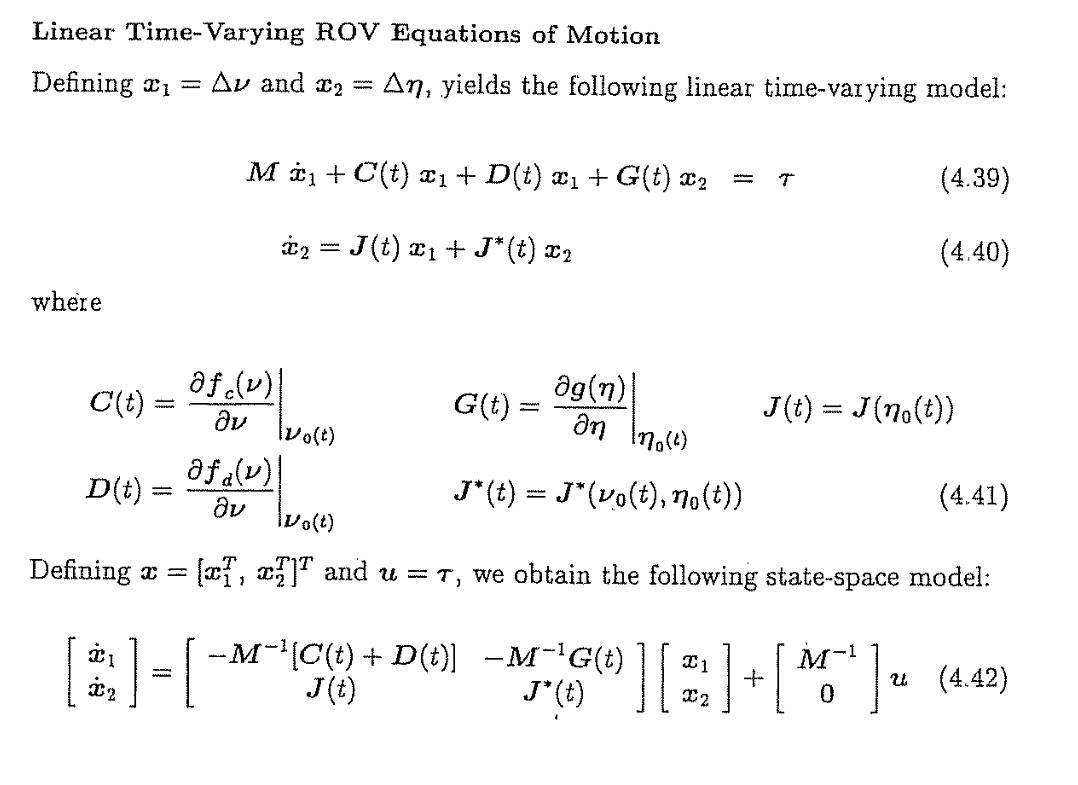

euler

    % calcules des jacobiennes
        Dj=subs(D,V,V_0);
        Dj = jacobian(Dj*V_0,V_0)

$$Dj = \left[\begin{array}{cccccc} {\mathrm{CD}}_{\mathrm{L1}}+\frac{{\mathrm{AF}}_{1}\,{\mathrm{CD}}_{\mathrm{Q1}}\,\rho \,\left|V_{01}\right|}{2}+\frac{{\mathrm{AF}}_{1}\,{\mathrm{CD}}_{\mathrm{Q1}}\,V_{01}\,\rho \,\mathrm{sign}\left(V_{01}\right)}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{CD}}_{\mathrm{L2}}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q2}}\,\rho \,\left|V_{02}\right|}{2}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q2}}\,V_{02}\,\rho \,\mathrm{sign}\left(V_{02}\right)}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{CD}}_{\mathrm{L3}}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q3}}\,\rho \,\left|V_{03}\right|}{2}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q3}}\,V_{03}\,\rho \,\mathrm{sign}\left(V_{03}\right)}{2} & 0 & 0 & 0\\ 0 & 0 & 0 & {\mathrm{CD}}_{\mathrm{L4}}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q4}}\,\rho \,\left|V_{04}\right|}{2}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q4}}\,V_{04}\,\rho \,\mathrm{sign}\left(V_{04}\right)}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & {\mathrm{CD}}_{\mathrm{L5}}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q5}}\,\rho \,\left|V_{05}\right|}{2}+\frac{{\mathrm{AF}}_{3}\,{\mathrm{CD}}_{\mathrm{Q5}}\,V_{05}\,\rho \,\mathrm{sign}\left(V_{05}\right)}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & {\mathrm{CD}}_{\mathrm{L6}}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q6}}\,\rho \,\left|V_{06}\right|}{2}+\frac{{\mathrm{AF}}_{2}\,{\mathrm{CD}}_{\mathrm{Q6}}\,V_{06}\,\rho \,\mathrm{sign}\left(V_{06}\right)}{2} \end{array}\right]$$

        
        Cj=subs(C,V,V_0);
        Cj = jacobian(Cj*V_0,V_0)

        
        Gj=subs(Ge,Ne,N_0);
        Gj = jacobian(Gj,N_0)

        
   % dérivée partiel de l'équation cinématique
      Jedn=subs(Je,[n1;n2],NODN);
      Je0=subs(Je,[n1;n2],N_0);
      J10=subs(J1,[n1;n2],N_0);
      
      Jstar=[J10,zeros(3,3);
             zeros(3,3),eye(3)]

$$Jstar = \left[\begin{array}{cccccc} \cos\left(N_{05}\right)\,\cos\left(N_{06}\right) & \cos\left(N_{06}\right)\,\sin\left(N_{04}\right)\,\sin\left(N_{05}\right)-\cos\left(N_{04}\right)\,\sin\left(N_{06}\right) & \sin\left(N_{04}\right)\,\sin\left(N_{06}\right)+\cos\left(N_{04}\right)\,\cos\left(N_{06}\right)\,\sin\left(N_{05}\right) & 0 & 0 & 0\\ \cos\left(N_{05}\right)\,\sin\left(N_{06}\right) & \cos\left(N_{04}\right)\,\cos\left(N_{06}\right)+\sin\left(N_{04}\right)\,\sin\left(N_{05}\right)\,\sin\left(N_{06}\right) & \cos\left(N_{04}\right)\,\sin\left(N_{05}\right)\,\sin\left(N_{06}\right)-\cos\left(N_{06}\right)\,\sin\left(N_{04}\right) & 0 & 0 & 0\\ -\sin\left(N_{05}\right) & \cos\left(N_{05}\right)\,\sin\left(N_{04}\right) & \cos\left(N_{04}\right)\,\cos\left(N_{05}\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right]$$

     
     Ac = [zeros(6,6),Jstar;
          -(M\ Gj),-(M\(Cj + Dj))];
%     Ac =jacobian(sime,[n1;n2;V]);
%     Ac =subs(Ac,[n1;n2;V],[N_0;V_0]);
    
    Bc = [zeros(6,8);M\Tm];
    
    Cc = jacobian([Ne;V],[n1;n2;V]);
    
    Dc = jacobian([Ne;V], U );

### Modèle réduit

%     eqr= eta==sqrt(1^2 - epsilon1^2 - epsilon2^2 - epsilon3^2)
%     stater=[n1;epsilon;V]
%     
%     E2r=[eta*eye(3)+skew(epsilon)]
%     
%    Jr=[E1,zeros(3,3);
%    zeros(3,3),(1/2)*E2r]
% 
%    Jrj=jacobian(Jr*[V],stater)
% 
%     Dj = jacobian(D*V,V)
%     Cj = jacobian(C*V,V)
%     Gj = jacobian(Gq,[n1;epsilon])
%     
%     Ac = [Jrj;
%          -(M\ Gj),-(M\(Cj + Dj))];
%     
%     Bc = [zeros(6,8);M\Tm];
%     
%     Cc = jacobian([stater],[stater]);
%     
%     Dc = jacobian([stater], U );
%    
%     
%    % Att=jacobian(reSim,[]);
%    % Btt=jacobian(reSim,U);.

#### Jacobienne pour modele non linéaire

Anq = jacobian(simq,[Nq;V]);
Bnq = jacobian(simq,[U]);
Cnq = jacobian([Nq;V],[Nq;V]);
Dnq = jacobian([Nq;V],[U]);

## Implémentation 

### Substituer les constantes du modèle du sous-marin

%% Chargement des paramètres
    cf = ConfigAUV8();

    constValues = [cf.d14 ...
                 cf.d58 ...
                 cf.a14 ...
                 cf.dz ...
                 cf.z ...
                 cf.mass ...
                 cf.volume ...
                 cf.height...
                 cf.AF ...
                 cf.I(1,:) ...
                 cf.I(2,:) ...
                 cf.I(3,:) ...
                 cf.RG ...
                 cf.RB ...
                 cf.CDL...
                 cf.CDQ...
                 cf.rho ...
                 cf.g];

% Substituer les constantes dans les équation différentielles
      simqpc=subs(simqp, constMec, constValues);
      simqc=subs(simq, constMec, constValues);
      simec=subs(sime, constMec, constValues);
      Gravity =subs(Ge, constMec, constValues);

% Substituer les constantes dans les Matrices
    Av=subs(Ac, constMec, constValues);
    Bv=subs(Bc, constMec, constValues);

    Anqv=subs(Anq, constMec, constValues);
    Bnqv=subs(Bnq, constMec, constValues);

### Linéariser au condition initials.

    % États initaux
    N0=[0;0;.2246;pi/4;0;0]

N0 =          0
         0
    0.2246
    0.7854
         0
         0


    V0=[0;0;0;0;0;0]

V0 =      0
     0
     0
     0
     0
     0


    
    %A0=double(subs(Av, [Ne;V], [N0;V0]));
    A0=double(subs(Av, [N_0;V_0], [N0;V0]));   
    B0=double(Bv);

## Étude

Ts=0.1;
nx = size(A0,1);
nu = size(B0,2);
M = expm([[A0 B0]*Ts; zeros(nu,nu+nx)]);
Ad = M(1:nx,1:nx);
Bd = M(1:nx,nx+1:nx+nu);
Cd = double(Cc);
Dd = double(Dc);
AUVPlant=ss(Ad,Bd,Cd,Dd,Ts);

% Création du controleur MPC.
    mpcobj =mpc(AUVPlant);

-->The "PredictionHorizon" property of "mpc" object is empty. Trying PredictionHorizon = 10.
-->The "ControlHorizon" property of the "mpc" object is empty. Assuming 2.
-->The "Weights.ManipulatedVariables" property of "mpc" object is empty. Assuming default 0.00000.
-->The "Weights.ManipulatedVariablesRate" property of "mpc" object is empty. Assuming default 0.10000.
-->The "Weights.OutputVariables" property of "mpc" object is empty. Assuming default 1.00000.
   for output(s) y1 y2 y3 y4 y5 y6 y7 y8 and zero weight for output(s) y9 y10 y11 y12 



% Étude de controllabilité
    c0=ctrb(A0,B0);
    nc=rank(c0)

nc = 12

    
% Étude de stabilité au point d'équilibre
    poles=eig(A0)

poles =          0
         0
         0
         0
    2.6730
    1.8973
   -4.5584
   -4.8137
   -3.3711
   -1.3028


### Générer les fonctions matlab

% Générer l'équation non linéaire (quaternion) avec perturbation pour
% simulation

    matlabFunction(transpose(simqpc),'File','AUVQuatPerturbedSimFcn',...
       'Vars',{[Nq;V],F_ext,U});
   
% Générer l'équation non linéaire (quaternion) sans perturbation pour le
% controlleur

   matlabFunction(transpose(simqc),'File','AUVQuatSimFcn',...
       'Vars',{[Nq;V],U});
   
% Générer l'équation non linéaire (Euler)   
   matlabFunction(transpose(simec),'File','AUVEulerSimFcn',...
       'Vars',{[Ne;V],F_ext,U});
   
% Générer les matrices jacobiennes (Euler)
    matlabFunction(Av, Bv, Cc, Dc,'File','AUVEulJacobianMatrix',...
        'Vars',{[N_0;V_0],U});  
    
% Générer les matrices jacobiennes (Quaternions)
    matlabFunction(Anqv, Bnqv, Cnq, Dnq,'File','AUVQuatJacobianMatrix',...
        'Vars',{[Nq;V],U});    


## Sous-fonctions personalisées

Ici ce trouve nos fonctions personalisées

### Matrice antisymétrique

function sm=skew(u) 
% Convertie un vecteur 3x1 en une matrice antisymétrique 3x3
    sm=[0,-u(3),u(2);
        u(3), 0, -u(1);
       -u(2), u(1), 0];
end